Representación de una función de transferencia en el plano Z. La función de transferencia en cuestión es:


$$H(z)=\frac{z}{z-1}$$


Lo primero es definir el espacio de los números complejos como plano de 2D

[R,I]=meshgrid(-2:0.05:2,-2:0.05:2);

Luego se crea cada uno de los valores de cada punto del plano complejo

Z=R+1i*I;

Ahora se procede a calcular la ganancia de la función de transferencia en cada uno de los puntos del plano complejo. Tenga en cuenta el uso del operador ./ que relaciona el numerador y el denominador, esto es porque la varaible Z es un arreglo pero no se opera como matriz

G=abs(Z./(Z-1));

Finalmente se realiza el gráfico en 3D

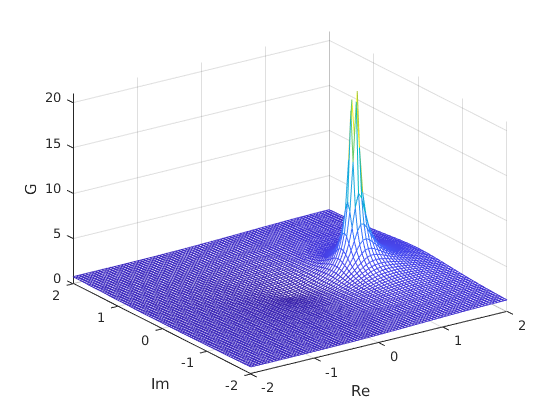

figure()
meshc(R,I,G)
xlabel('Re')
ylabel('Im')
zlabel('G')